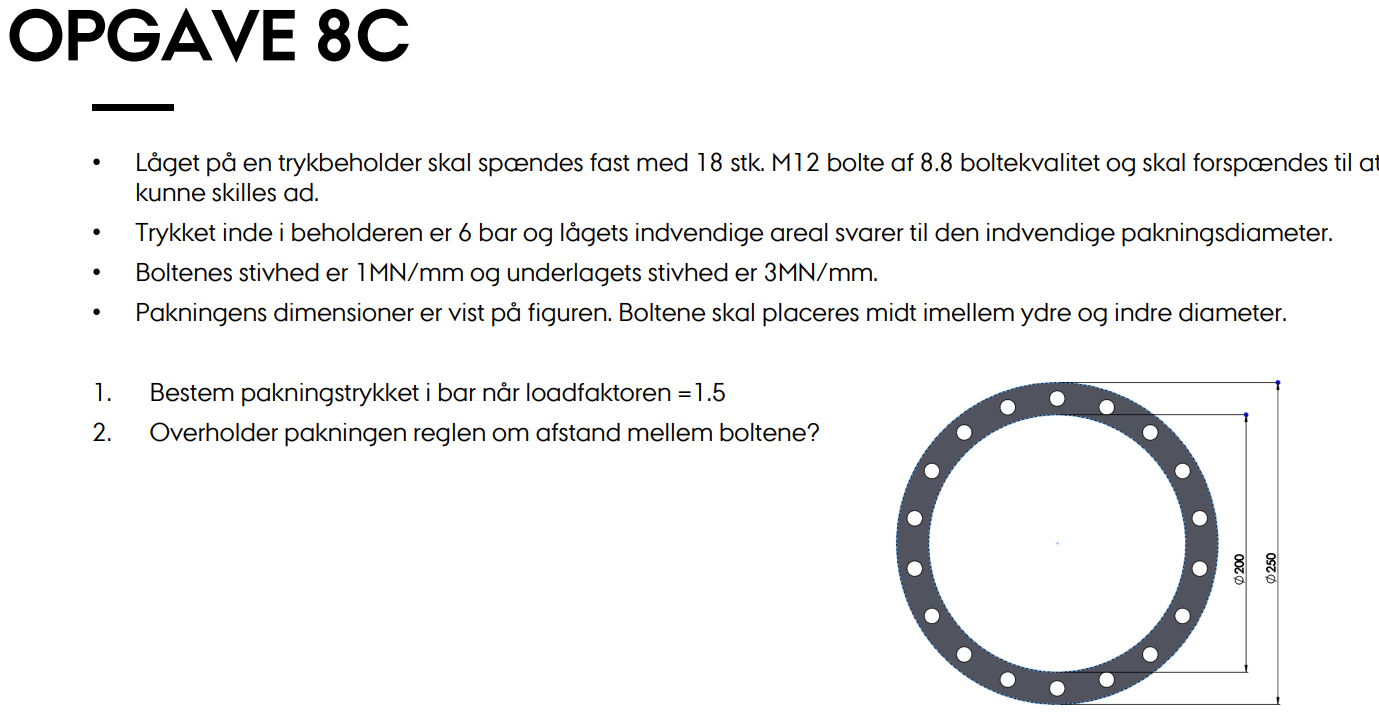

format short
u = symunit;
% separateUnits(x)
% separateUnits(x_si)


N = 18; %M12 bolte 8.8

d_y = 250 * u.mm; % ydre diameter
d_i = 200 * u.mm; % indre diameter
D_b = (d_y + d_i)/2; %bolt diameteren

d = 12 * u.mm; %skaftdiameteren på boltene %M12

A_g = pi/4 * (d_y^2 - d_i^2 - N * d^2); % Arealet af pakningen% her trækkes bolt arealet af boltene fra (N * d^2).
A_g_ = vpa(A_g,5)

$$A\_g\_ = 15636.0\,{\mathrm{mm}}^{2}$$


Sut = 800 * u.MPa; % Brud styrken
Sy = Sut * 0.8 * u.MPa; % Flyde spændingen
% Sp = 0.85 * Sy % bolte 3 % udregnet

Sp = 600 *u.MPa; %0.85 * Sy; % tabel 8-11 i shigleys eller onenote

A_t = 84.3 * u.mm^2; %opslag i tabel 8.1 i shigleys

F_p = Sp * A_t %forspænding

$$F\_p = 50580\,\mathrm{MPa}\,{\mathrm{mm}}^{2}$$

% Fp_ = vpa(unitConvert(Fi, u.kN))

F_i = 0.75 * F_p

$$F\_i = 37935\,\mathrm{MPa}\,{\mathrm{mm}}^{2}$$

F_i_ = vpa(unitConvert(F_i, u.kN),3)

$$F\_i\_ = 37.9\,\mathrm{kN}$$

A_i = pi * (d_i/2)^2

$$A\_i = 10000\,\pi \,{\mathrm{mm}}^{2}$$

P = 6*u.bar * A_i; % udfra kommende tryk
vpa(unitConvert(P, u.kN), 4)

$$ans = 18.85\,\mathrm{kN}$$

P_bolt = P/N; %Ekstern last pr bolt
P_bolt_ = vpa(unitConvert(P, u.kN), 4)

$$P\_bolt\_ = 18.85\,\mathrm{kN}$$

n = 1.5; %load factor

k_b = 1 * u.MN * u.mm; %boltens stivhedsfaktor
k_m = 3 * u.MN * u.mm; %underlagets stivhedsfaktor

C =  k_b/(k_b + k_m); %stivhedsfaktoren

F_m = vpa(unitConvert(F_i - n*P_bolt * (1-C), u.MPa), 3)

$$F\_m = 0.0368\,\mathrm{MPa}\,m^{2}$$


% F_m * N = p_g * A_g
p_g = F_m * N / A_g;
p_g_ = vpa(unitConvert(p_g, u.bar), 5)

$$p\_g\_ = 423.15\,\mathrm{bar}$$




%kontrol
test = double(pi *D_b / (N*d))

test = 3.2725


if 3 < test < 6
    disp("OK! Antal bolte fordelt på boltcirkel diameteren er mellem 3 og 6 bolte diametre imellem boltene og dermed OK!")
else
    disp("IKKE ok jf. shigleys")
end

OK! Antal bolte fordelt på boltcirkel diameteren er mellem 3 og 6 bolte diametre imellem boltene og dermed OK!
